clear all 
%{

This is the script for running the test data with a given trained model. It
calls Predict_Temp(). The test data points are some subset of the 100
experimental data points. 

%}


load("Compileddata.mat") % 100 data points saved in array 
Conversion=data(:,6);    %the conversion dat 
avgtemp=data(:,7:end);   %the experimental temperature measurements
power_dissp=data(:,5);   %the experimental power dissipaiton
totflow=data(:,4);       %the flow rate in slpm 
Lvals=data(:,2);         %the reactor length 
st=data(:,1);            %the reactor configuration (1-5 for 5 different expeirmental configurations).  

i=1; 
curves=[2,14,20,23,36,55,61,78,89,92]; %test data points 

for n=[2,14,20,23,36,55,61,78,89,92] %test data points 

    disp(n)


if st(n)==1 %structure 1 
    structure=[1 1 1 1 1 1 1 1 1 1 1 1 1 1]; %the array of structure electrical conductivities
    dec_struct=0; %the decimal number associated with a given binary array (structure)
elseif st(n)==2 %structure 2
    structure=[1 1 1 1 1 1 1 1 1 1 1 1 1 1];
    dec_struct=0; 
 
elseif st(n)==3 %structure 3
    structure=[1 1 2 1 2 2 2 1 1 2 2 1 1 1];
    dec_struct=2968; 

elseif st(n)==4 %structure 4
    structure=[2 2 2 2 1 2 1 1 1 1 1 1 1 2]; 
    dec_struct=15617; 

else %structure 5
    structure=[1 2 1 1 1 2 1 2 1 1 2 1 2 2]; 
    dec_struct=4427; 
 
end

%structure initialization 
L=Lvals(n); %length
flow=totflow(n); %flow rate in slpm

dL=0.012; %m, distance from end of reactor to last sensor point in reactor zone 
dsensor=0.015; %m, distance between adjacent sensor points 
start=L-dL-12*0.015; %m, coordinate of first sensor point in reactor zone
axial=start:0.015:start+14*0.015; %m, axial position vector associated with exp. temep. data 
dS=L/length(structure); %m, width of each lattice section
nump=150; %number of points in temperature prediction 
xval=linspace(0,L,nump); %m, axial position associated with model temp. data 

checkfit=interp1(axial,avgtemp(n,:),xval,"linear"); %linear interpolation of experimental data 

Tset=max(checkfit); %set maximum temerature of model to match experimental data 


    Tinmin=100;
    Tinmax=400;
    Pinmin=90;
    Pinmax=200; 
    [~,~,P,T,~,~,~]=...
        Predict_Temp(dec_struct,Tinmin,Tinmax,Pinmin,Pinmax,flow,Tset,10,2.34); %Cr=2.34


    Tinmin=T-10-2*rand(1);
    Tinmax=T+10+2*rand(1);
    Pinmin=P-10-2*rand(1);
    Pinmax=P+10+2*rand(1);

    [Temp(i,:),xval,bestP(i),bestT(i),convo(i),minmet(i),struct(i,:)]=...
        Predict_Temp(dec_struct,Tinmin,Tinmax,Pinmin,Pinmax,flow,Tset,0.5,2.34); %Cr=2.34



%Error 
MSE_OG=sum((Temp(i,:)-checkfit).^2); 
AVG=sum((checkfit-mean(checkfit)).^2); 
RMSE_OG=sqrt((1/150)*MSE_OG); %RMSE error 
R_OG=1-MSE_OG/AVG; %r^2 error 


Error(i,:)=[n,R_OG,RMSE_OG]; %array of test point index and error values 

i=i+1; 
end

     2

    14

    20

    23

    36

    55

    61

    78

    89

    92



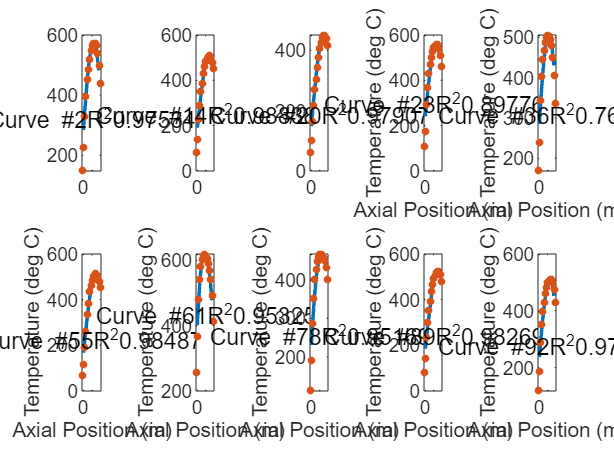

%plot curves 

tiledlayout(2,5)

nexttile
plot(xval,Temp(1,:),axial,avgtemp(curves(1),:),'.',...
    "LineWidth",1.5,"MarkerSize",10)
text(0.1, min(Temp(1,:)-20), string("Curve #"+Error(1,1)+"R^2"+Error(1,2)),...
    'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom')

nexttile
plot(xval,Temp(2,:),axial,avgtemp(curves(2),:),'.',...
    "LineWidth",1.5,"MarkerSize",10)
text(0.1, min(Temp(2,:)-20), string("Curve #"+Error(2,1)+"R^2"+Error(2,2)),...
    'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom')

nexttile
plot(xval,Temp(3,:),axial,avgtemp(curves(3),:),'.',...
    "LineWidth",1.5,"MarkerSize",10)
text(0.1, min(Temp(3,:)-20), string("Curve #"+Error(3,1)+"R^2"+Error(3,2)),...
    'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom')

nexttile
plot(xval,Temp(4,:),axial,avgtemp(curves(4),:),'.',...
    "LineWidth",1.5,"MarkerSize",10)
xlabel("Axial Position (m)")
ylabel("Temperature (deg C)")
text(0.1, min(Temp(4,:)-20), string("Curve #"+Error(4,1)+"R^2"+Error(4,2)),...
    'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom')

nexttile
plot(xval,Temp(5,:),axial,avgtemp(curves(5),:),'.',...
    "LineWidth",1.5,"MarkerSize",10)
xlabel("Axial Position (m)")
ylabel("Temperature (deg C)")
text(0.1, min(Temp(5,:)-20), string("Curve #"+Error(5,1)+"R^2"+Error(5,2)),...
    'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom')

nexttile
plot(xval,Temp(6,:),axial,avgtemp(curves(6),:),'.',...
    "LineWidth",1.5,"MarkerSize",10)
xlabel("Axial Position (m)")
ylabel("Temperature (deg C)")
text(0.1, min(Temp(6,:)-20), string("Curve #"+Error(6,1)+"R^2"+Error(6,2)),...
    'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom')

nexttile
plot(xval,Temp(7,:),axial,avgtemp(curves(7),:),'.',...
    "LineWidth",1.5,"MarkerSize",10)
xlabel("Axial Position (m)")
ylabel("Temperature (deg C)")
text(0.1, min(Temp(7,:)-20), string("Curve #"+Error(7,1)+"R^2"+Error(7,2)),...
    'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom')

nexttile
plot(xval,Temp(8,:),axial,avgtemp(curves(8),:),'.',...
    "LineWidth",1.5,"MarkerSize",10)
xlabel("Axial Position (m)")
ylabel("Temperature (deg C)")

text(0.1, min(Temp(8,:)-20), string("Curve #"+Error(8,1)+"R^2"+Error(8,2)),...
    'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom')

nexttile
plot(xval,Temp(9,:),axial,avgtemp(curves(9),:),'.',...
    "LineWidth",1.5,"MarkerSize",10)
xlabel("Axial Position (m)")
ylabel("Temperature (deg C)")

text(0.1, min(Temp(9,:)-20), string("Curve #"+Error(9,1)+"R^2"+Error(9,2)),...
    'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom')

nexttile
plot(xval,Temp(10,:),axial,avgtemp(curves(10),:),'.',...
    "LineWidth",1.5,"MarkerSize",10)
xlabel("Axial Position (m)")
ylabel("Temperature (deg C)")

text(0.1, min(Temp(10,:)-20), string("Curve #"+Error(10,1)+"R^2"+Error(10,2)),...
    'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom')